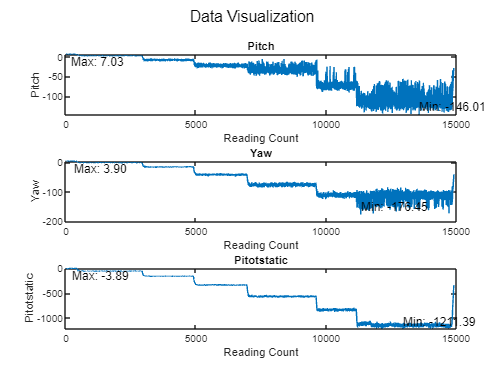

% Specify the file name
filename = 'C:\Users\TrevorBailey.MSI\Documents\PlatformIO\Projects\MVP1\speed_ramp.csv';

% Read the data from the CSV file
data = readmatrix(filename);

% Extract columns
Reading_Count = data(:, 1);
Pitch = data(:, 2);
Yaw = data(:, 3);
Pitotstatic = data(:, 4);

% Plot the data
figure;
subplot(3, 1, 1);
plot(Reading_Count, Pitch);
title('Pitch');
xlabel('Reading Count');
ylabel('Pitch');

% Add text for min and max values of Pitch
text(Reading_Count(Pitch == min(Pitch)), min(Pitch), sprintf('Min: %.2f', min(Pitch)), 'VerticalAlignment', 'bottom');
text(Reading_Count(Pitch == max(Pitch)), max(Pitch), sprintf('Max: %.2f', max(Pitch)), 'VerticalAlignment', 'top');

subplot(3, 1, 2);
plot(Reading_Count, Yaw);
title('Yaw');
xlabel('Reading Count');
ylabel('Yaw');

% Add text for min and max values of Yaw
text(Reading_Count(Yaw == min(Yaw)), min(Yaw), sprintf('Min: %.2f', min(Yaw)), 'VerticalAlignment', 'bottom');
text(Reading_Count(Yaw == max(Yaw)), max(Yaw), sprintf('Max: %.2f', max(Yaw)), 'VerticalAlignment', 'top');

subplot(3, 1, 3);
plot(Reading_Count, Pitotstatic);
title('Pitotstatic');
xlabel('Reading Count');
ylabel('Pitotstatic');

% Add text for min and max values of Pitotstatic
text(Reading_Count(Pitotstatic == min(Pitotstatic)), min(Pitotstatic), sprintf('Min: %.2f', min(Pitotstatic)), 'VerticalAlignment', 'bottom');
text(Reading_Count(Pitotstatic == max(Pitotstatic)), max(Pitotstatic), sprintf('Max: %.2f', max(Pitotstatic)), 'VerticalAlignment', 'top');

% Adjust the figure layout
sgtitle('Data Visualization');